% experiment2.mlx
% Tranfer Learning with GoogleNET

clc; clear; close all;
cd('~/Documents/jorgeMunoz/docMicrostructuresAI/experiments/conMatlab/experiment2-diciembre2022/methods/')
gpu = gpuDevice

gpu =   CUDADevice with properties:

                      Name: 'NVIDIA GeForce RTX 3080'
                     Index: 1
         ComputeCapability: '8.6'
            SupportsDouble: 1
             DriverVersion: 11.4000
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152 (49.15 KB)
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 10501423104 (10.50 GB)
           AvailableMemory: 9698410496 (9.70 GB)
       MultiprocessorCount: 68
              ClockRateKHz: 1800000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


DatasetPath= '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

DatasetPath = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/224x224_SIMETRICA'

%520x514 px
%DatasetPath = '/home/cima/Documents/jorgeMunoz/docMicrostructuresAI/materiales/microscopioMuestrasCIMA-EDIT/520x514_SIMETRICA'


imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

[imdsTrain, imdsVal, imdsTest] = splitEachLabel(imds, 0.7, 0.2, 0.1,"randomized");
labelCount = countEachLabel(imdsTrain)

labelCount = 3×2 table
           Label           Count
    ___________________    _____

    annealing              4480 
    quenching              4480 
    quenching+tempering    4480 


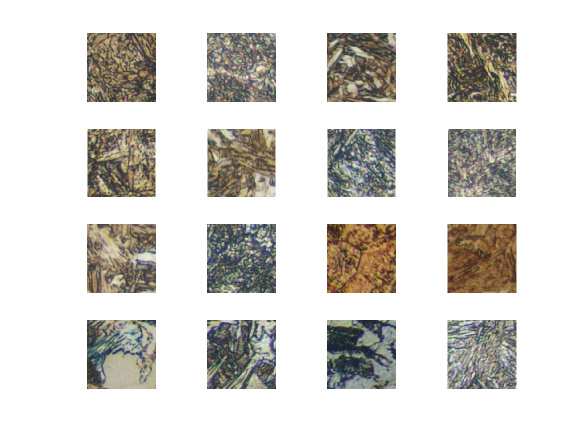

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end



net = googlenet;
%analyzeNetwork(net)

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


%Resized_Training_Dataset = augmentedImageDatastore(Input_Layer_Size, Training_Dataset, "ColorPreprocessing","gray2rgb");
%Resized_Validation_Dataset = augmentedImageDatastore(Input_Layer_Size ,Validation_Dataset, "ColorPreprocessing","gray2rgb");
%Resized_Testing_Dataset = augmentedImageDatastore(Input_Layer_Size ,Testing_Dataset, "ColorPreprocessing","gray2rgb");
%Feature_Learner = net.Layers(142).Name
%Output_Classifier = net.Layers(144).Name
lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 3

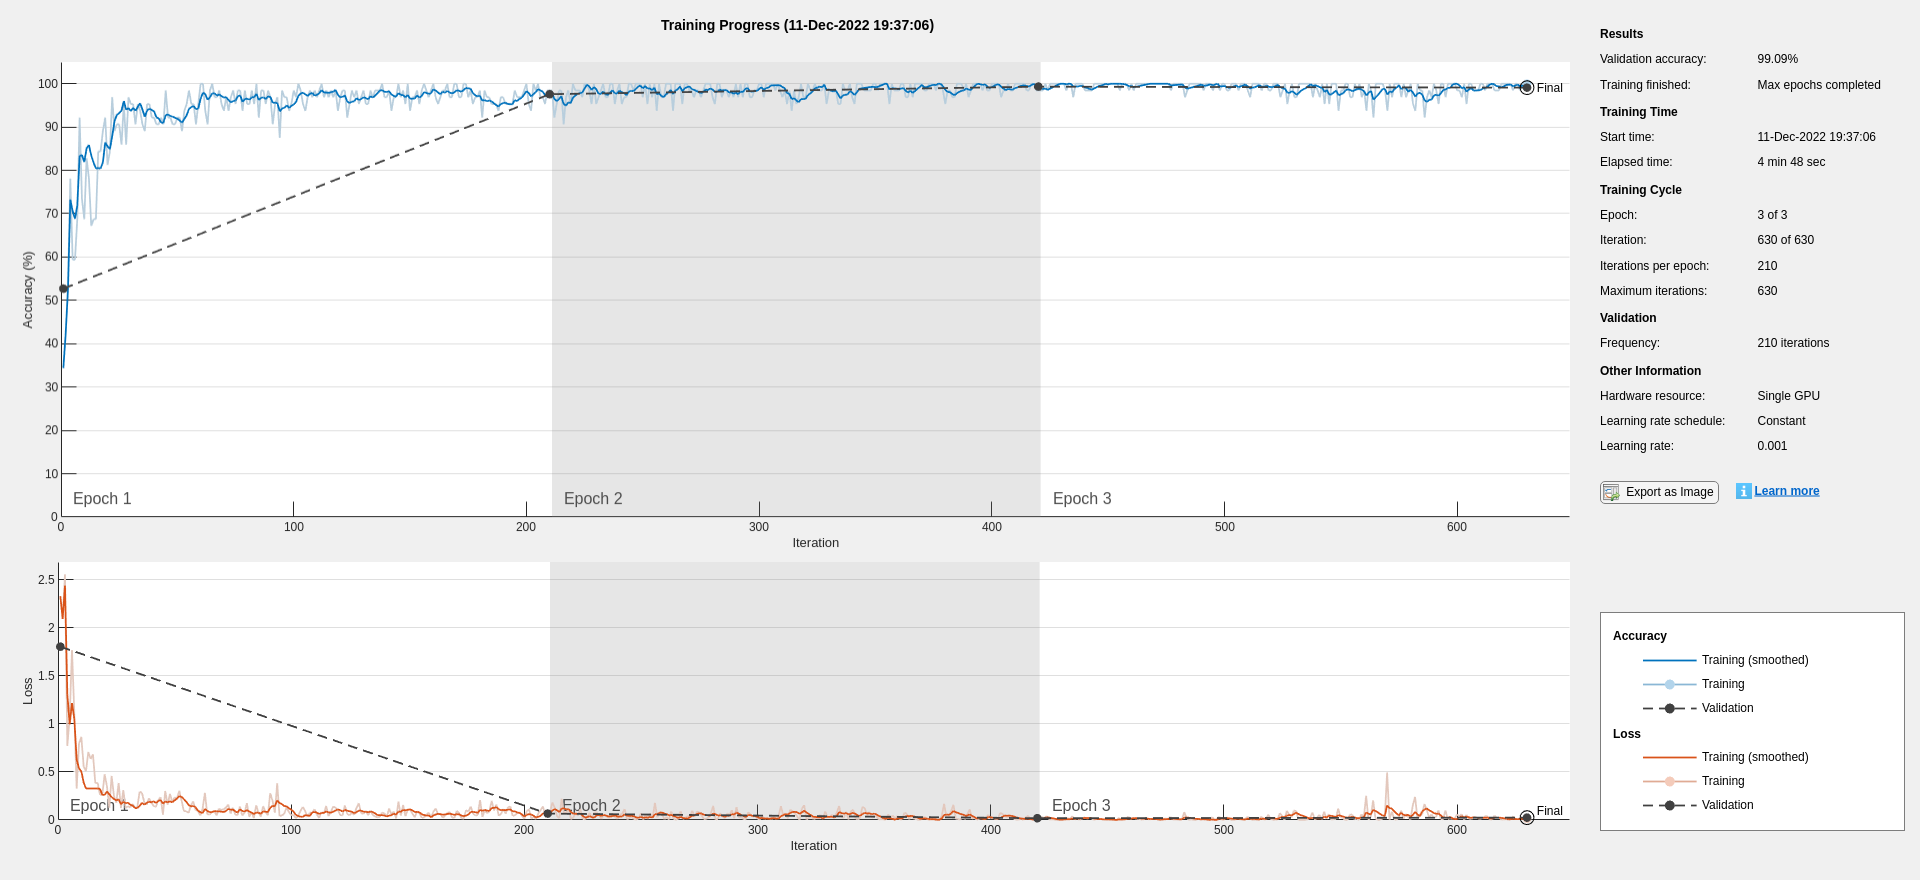


newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name', 'Steel Feature Learner', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);

lgraph = replaceLayer(lgraph,'loss3-classifier', newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph, 'output', newClassLayer);
Network_Architecture = layerGraph(net);

Minibatch_Size = 64;
validationFrequency = floor(numel(imdsTrain.Files)/Minibatch_Size);
Training_Options = trainingOptions('sgdm', ...
    'MiniBatchSize', Minibatch_Size, ...
    'MaxEpochs', 3, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsVal, ...
    'ValidationFrequency', validationFrequency, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

%Code for resizing (just in case there are images in different
%resolution than 224x244
%imdsTrain = augmentedImageDatastore(inputSize, imdsTrain, 'ColorPreprocessing', 'gray2rgb');
%imdsVal = augmentedImageDatastore(inputSize, imdsVal, 'ColorPreprocessing', 'gray2rgb');
%imdsTest = augmentedImageDatastore(inputSize, imdsTest, 'ColorPreprocessing', 'gray2rgb');



[net tr]= trainNetwork(imdsTrain, lgraph, Training_Options);


% Accuracy (Val)
[YPred,probs] = classify(net,imdsVal);
accuracyVal = mean(YPred == imdsVal.Labels)

accuracyVal = 0.9909

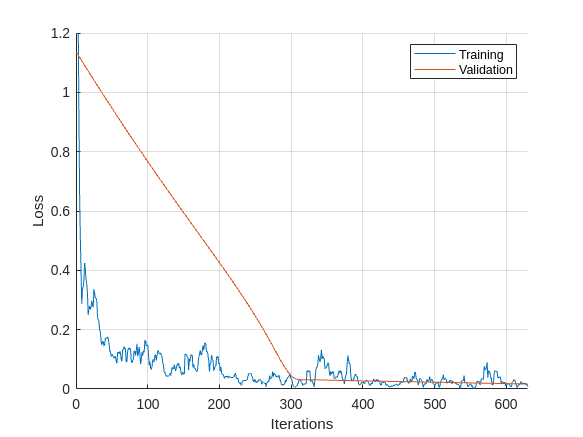

%Plot train 
%Loss
figure;
x = [1:630];
yl = tr.TrainingLoss;
yvl = tr.ValidationLoss;
plot(x, smooth(yl));
hold on;
plot(x, smooth(yvl));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [0 630 0 1.2] );
grid on;
xlabel('Iterations');
ylabel('Loss');

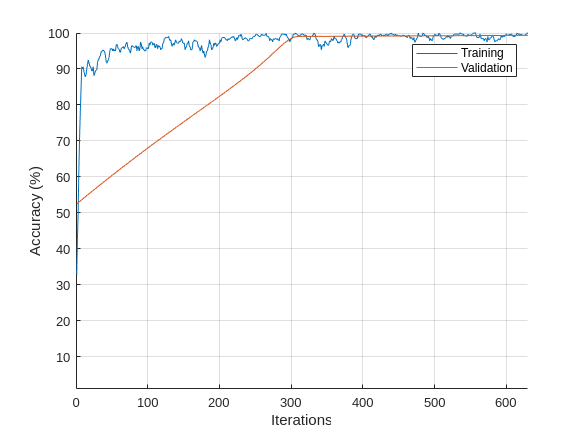


%Accuracy
figure;
x = [1:630];
y = tr.TrainingAccuracy;
yv = tr.ValidationAccuracy;
%yi = smooth(y);

plot(x, smooth(y));
hold on;
plot(x, smooth(yv));
set(gca, 'box', 'off')
legend('Training','Validation');
axis( [  0     630    1    100 ] );
grid on;
xlabel('Iterations');
ylabel('Accuracy (%)');

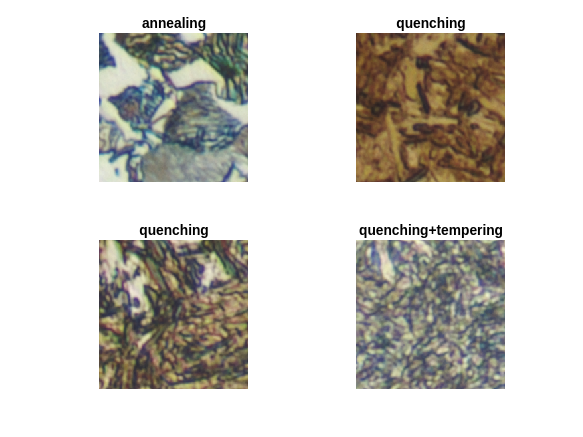


%TEST

[YPredTest,scores] = classify(net,imdsTest);
idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    %label = YPred(idx(i));
    label = YPredTest(idx(i));
    title(string(label));
end


YTest = imdsTest.Labels;
accuracyTest = mean(YPredTest == YTest)

accuracyTest = 0.9938

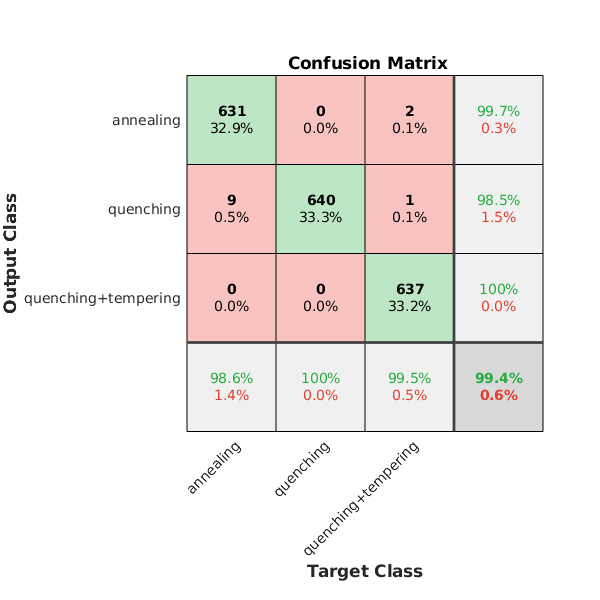

plotconfusion(YTest, YPredTest)

T = cMetrics(YTest, YPredTest)

Accuracy = 99.38%

T = 5×5 table
                           Precision    Recall      Fallout     Specificity      F1   
                           _________    _______    _________    ___________    _______

    annealing               0.99684     0.98594    0.0015625      0.99844      0.99136
    quenching               0.98462           1    0.0078125      0.99219      0.99225
    quenching+tempering           1     0.99531            0            1      0.99765
    Avg                     0.99382     0.99375     0.003125      0.99688      0.99375
    WgtAvg                  0.99382     0.99375     0.003125      0.99687      0.99375


% For Matthew correlation coefficient
confM = confusionmat(YPredTest, YTest);
multiMetrics = multiclass_metrics_special(confM);

writetable(T,'metricasGooglenet.xls')

save('experiment2Workspace.mat')


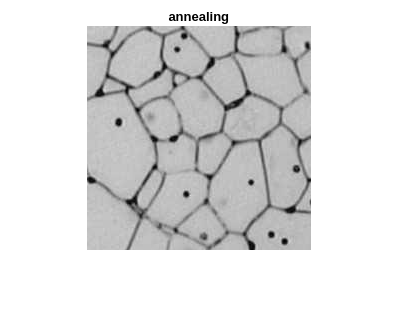

%Predict random images

im = imread('imagenesParaProbar/ferri1.jpeg');
%im = imread('imagenesParaProbar/ferri2.jpeg');
%im = imread('imagenesParaProbar/martensc.jpg');
%im = imread('imagenesParaProbar/martens2c.jpg');
%im = imread('imagenesParaProbar/martens3c.jpg');
%im = imread('imagenesParaProbar/reco1c.jpg');
%im = imread('imagenesParaProbar/reco2c.jpg');
%im = imread('imagenesParaProbar/reco3c.tif');
%im = imread('imagenesParaProbar/revec.tif');
%im = imread('imagenesParaProbar/martens4c.tif');
%im = imread('imagenesParaProbar/martens5c.jpg');
inputSize = net.Layers(1).InputSize;

% Se toma un recorte central de 224x224 de la imagen
targetSize = [224 224];
r = centerCropWindow2d(size(im), targetSize);
im = imcrop(im, r);
%im = imresize(im, inputSize(1:2));
%Classify image
[label,scores] = classify(net,im);
figure
imshow(im)
title(string(label))

scores

scores = 1×3 single row vector
    1.0000    0.0000    0.0000
